
g = @(x,y) exp(x.^2./2+ y.^2/2);
f = @(x,y) (1 + x.^2 +y.^2) .* exp(x.^2+y.^2);
g = @(x,y)-sqrt(2-x.^2-y.^2);
f = @(x,y) 2*(2-x.^2-y.^2).^(-2);
g = @ g_C1; % C1 example
f =  @ f_C1;

N = 2^4;
min_g = -g(0,0.5);
max_f = f(1,1);
R=sqrt(2);
S_h = @(x,y) min_g +1/2*(x.^2+y.^2-R^2)*sqrt(max_f);
omega_h = @(x,y) g(x,y)-S_h(x,y);
int_omega_h = @(x,y) 0;
h=1/N;
alpha=1/2;
beta=1/2;
delta = h^alpha;
theta = h^beta;
U = generate_intial_guess(int_omega_h,omega_h,N,N);
[U1,P_modyfied]=convexfy_function(N,U);

[X,Y]= meshgrid(0:h:1,0:h:1);
T=zeros(N^2*2,3);
node=0;
for i=1:N
    for j=1:N
        node=node+1;
        T(node,1)=j+(N+1)*(i-1);
        T(node,2)=j+(N+1)*(i-1)+1;
        T(node,3)=j+(N+1)*(i-1)+1+N+1;
        node=node+1;
        T(node,1)=j+(N+1)*(i-1);
        T(node,2)=j+(N+1)*(i-1)+N+1;
        T(node,3)=j+(N+1)*(i-1)+1+N+1;
    end
end
for i=1:N+1
    for j=1:N+1
        U1(i,j) = U1(i,j) +S_h((j-1)*h,(i-1)*h);
    end
end
error=zeros(1,1);
ite=0;
F=zeros(N-1,N-1);
for i=1:N-1
    for j=1:N-1
        F(i,j) = f(j*h,i*h);
    end
end
while 1
    U1=lift_u_all(U1,N,f,delta,theta);
    [~,TU] = T_epsilon_operator(U1,N,delta,theta);
    ite=ite+1;
    error(ite) = norm(F-TU);
    if mod(ite,5) == 0
        fprintf('iteration number:');
        disp(ite);
        fprintf('error:');
        disp(error(ite));
    end
    if error(ite)<1e-8*error(1)
        break
    end
end

iteration number:

     5



error:

    2.6618



iteration number:

    10



error:

    0.1866



iteration number:

    15



error:

    0.0062



iteration number:

    20



error:

   2.1517e-04



iteration number:

    25



error:

   1.0898e-05



iteration number:

    30



error:

   7.0929e-07



iteration number:

    35



error:

   1.0586e-07



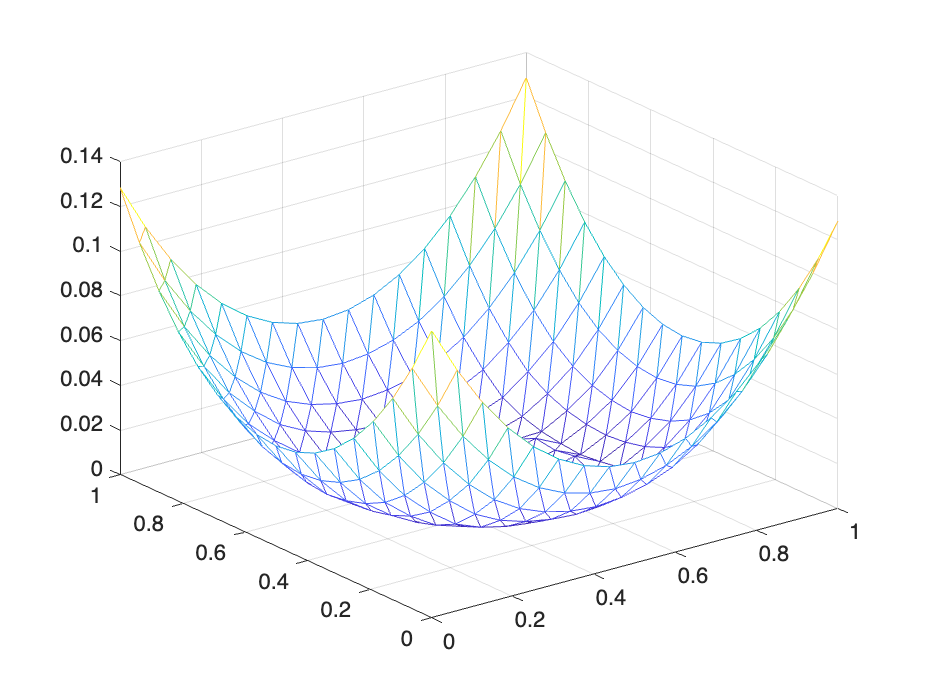

U0=zeros(N+1,N+1);
for i=1:N+1
    for j=1:N+1
        U0(i,j) = g((j-1)*h,(i-1)*h);
    end
end
L_infty_error = max(max(abs(U0-U1)));
L_2_error = sqrt(norm(U0-U1,2)^2*h^2);
trimesh(T,X,Y,U1);

fprintf('iteration number:');

iteration number:

disp(ite);

    35



fprintf('L infty error');

L infty error

disp(L_infty_error);

    0.0106

